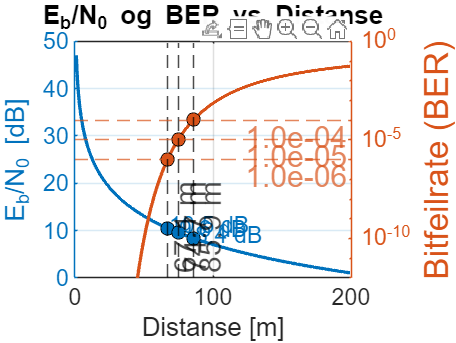

clc; clear; close all;

% Konstanter
c = 3e8;             % Lysfart (m/s)
f = 2.4e9;           % Frekvens (Hz)
lambda = c / f;      % Bølgelengde (m)

% Gitte parametere
EIRP = -20.5;        % dBW
L0 = 12;             % Systemtap (dB)
N0 = -144;           % Støytetthet (dBW/Hz)
Gr = 2.0;            % Mottakerantennens vinning (dBi)
Rb = 26.4;           % Bitrate (dBHz)

% Definer avstand (LINEÆR skala)
d = linspace(1, 200, 1000); % Fra 1 m til 200 m

% Friromstap (Path loss)
L_s = 20*log10(4 * pi * d / lambda); % dB

% Linkbudsjett beregning
Eb_N0_dB = EIRP - L_s - L0 + Gr - Rb - N0; % dB

% Konverter Eb/N0 til lineær verdi
Eb_N0_linear = 10.^(Eb_N0_dB / 10);

% BER for OQPSK/QPSK
BER = qfunc(sqrt(2 * Eb_N0_linear));

% Definer flere BER-grenser
BER_thresholds = [1e-6, 1e-5, 1e-4]; 

% --- PLOT ---
figure;

% Bit Energy to Noise Ratio (Eb/N0) Plot (venstre y-akse)
yyaxis left
plot(d, Eb_N0_dB, 'LineWidth', 2); % Plotter Eb/N0 på venstre akse
ylabel('E_b/N_0 [dB]', 'FontSize', 20);
xlabel('Distanse [m]', 'FontSize', 20);
grid on;
title('E_b/N_0 og BER vs Distanse', 'FontSize', 20);
set(gca, 'FontSize', 14);  % Øker skriftstørrelse for akselabels
hold on;

% BER Plot (høyre y-akse)
yyaxis right
semilogy(d, BER, 'LineWidth', 2);  % Gjør y-aksen logaritmisk for BER
ylabel('Bitfeilrate (BER)', 'FontSize', 20);
set(gca, 'YScale', 'log');  % Setter logaritmisk skala for høyre akse
ylim([1e-12, 1]); % Justert BER y-akse

% Iterer over flere BER-grenser og plotter maksimal avstand
for i = 1:length(BER_thresholds)
    % Finn nærmeste distanse hvor BER <= BER_threshold
    idx = find(BER >= BER_thresholds(i), 1, 'first');
    max_distance = d(idx);
    
    % Hent E_b/N_0-verdien ved denne distansen
    Eb_N0_at_maxDist = Eb_N0_dB(idx);
    yyaxis right
    % Plotter maksimal distanse for hver BER-grense
    plot(max_distance, BER(idx), 'ko', 'MarkerFaceColor', [0.850, 0.325, 0.098], 'MarkerSize', 8);
    
    % Legger til en stiplet linje på den aktuelle BER-grensen
    yline(BER_thresholds(i), '--', sprintf('%.1e', BER_thresholds(i)), 'LabelVerticalAlignment', 'bottom', 'LabelHorizontalAlignment', 'right','Color',[0.850, 0.325, 0.098],'FontSize',18);
    xline(max_distance, '--k', sprintf('%.1f m', max_distance), 'LabelVerticalAlignment', 'bottom', 'LabelHorizontalAlignment', 'right','FontSize',18);

    yyaxis left
    plot(max_distance, Eb_N0_at_maxDist, 'ko', 'MarkerFaceColor', [0, 0.447, 0.741], 'MarkerSize', 8);
    text(max_distance+1, Eb_N0_at_maxDist+0.7, sprintf('%.1f dB', Eb_N0_at_maxDist), 'FontSize', 14, 'Color', [0, 0.447, 0.741]);
end

hold off;